##  1 Harmonic Detection

%loading data
load('signal321.mat')
z = xn_test;  % Assign the signal to 'x'
fs = 128;  % Sampling frequency
N_total = length(z);  % Total number of samples

disp(['Total number of samples: ', num2str(N_total)]);

Total number of samples: 1793


%subsets
S1 = xn_test(1:128);
S2 = xn_test(1:256);
S3 = xn_test(1:512);
S4 = xn_test(1:1024);
S5 = xn_test(1:1792);

subsets = {S1, S2, S3, S4, S5};


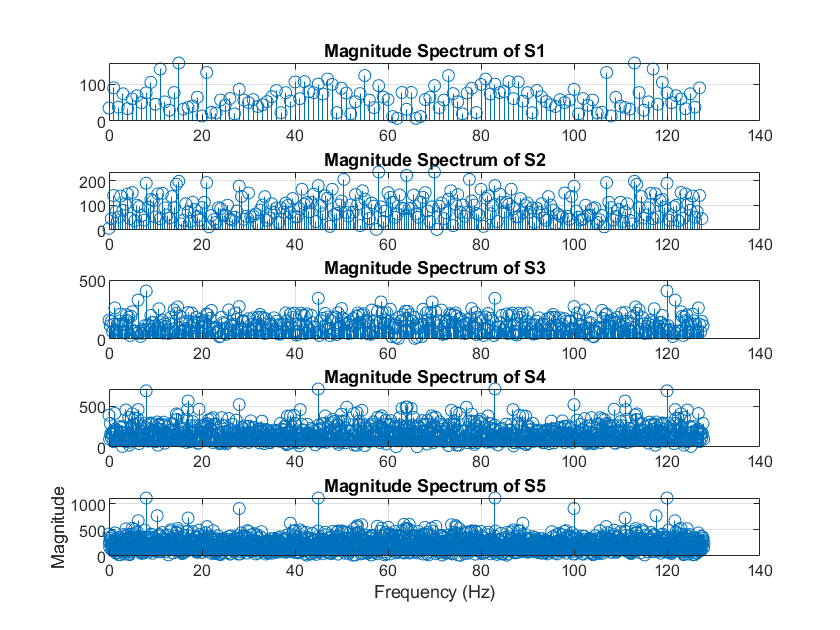

%plotting DFT magnitudes
for i = 1:5
    subset = subsets{i};
    X = fft(subset);  % Compute DFT
    X_mag = abs(X);
    freq = (0:length(X)-1) * (fs / length(X));  % Frequency vector
    subplot(5, 1, i);
    stem(freq,X_mag ); 
    title(['Magnitude Spectrum of S' num2str(i)]);
    grid on;
end
 xlabel('Frequency (Hz)');
    ylabel('Magnitude');

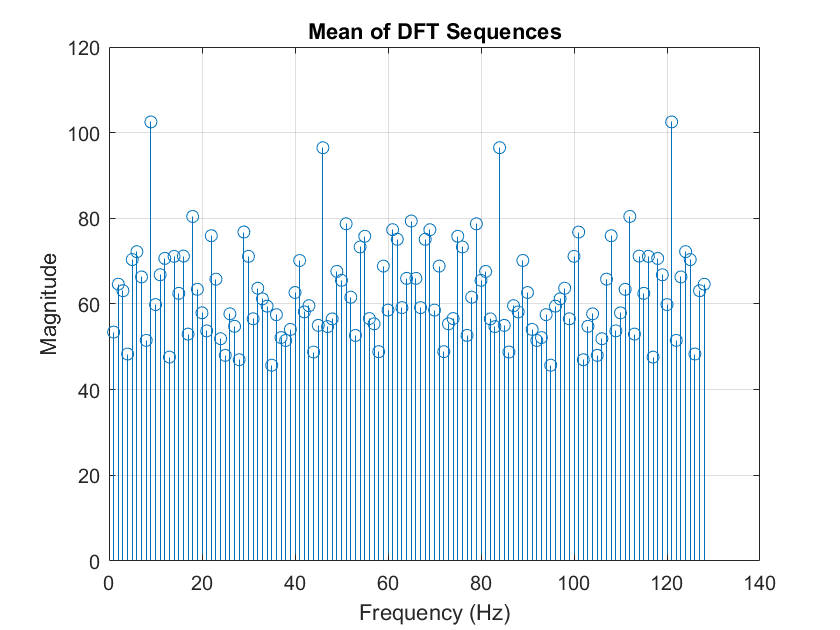

%plotting DFT magnitued with DFT averaging
    clf;
% Initialize parameters
total_samples = length(z);
L = 14;
K = 128;
i = 1; j=128;
mean_dft = 0;
for n = 1:L
 subset = z(i:j);
 dft_mag = abs(fft(subset, K));
 mean_dft = mean_dft + dft_mag;

 i = j+1;
 j = j+K;
end
mean_dft = mean_dft / L;
% Plot the magnitude 
stem(mean_dft);
title('Mean of DFT Sequences');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on

signal_file = load('signal321.mat');
signal_data = signal_file.xn_test;


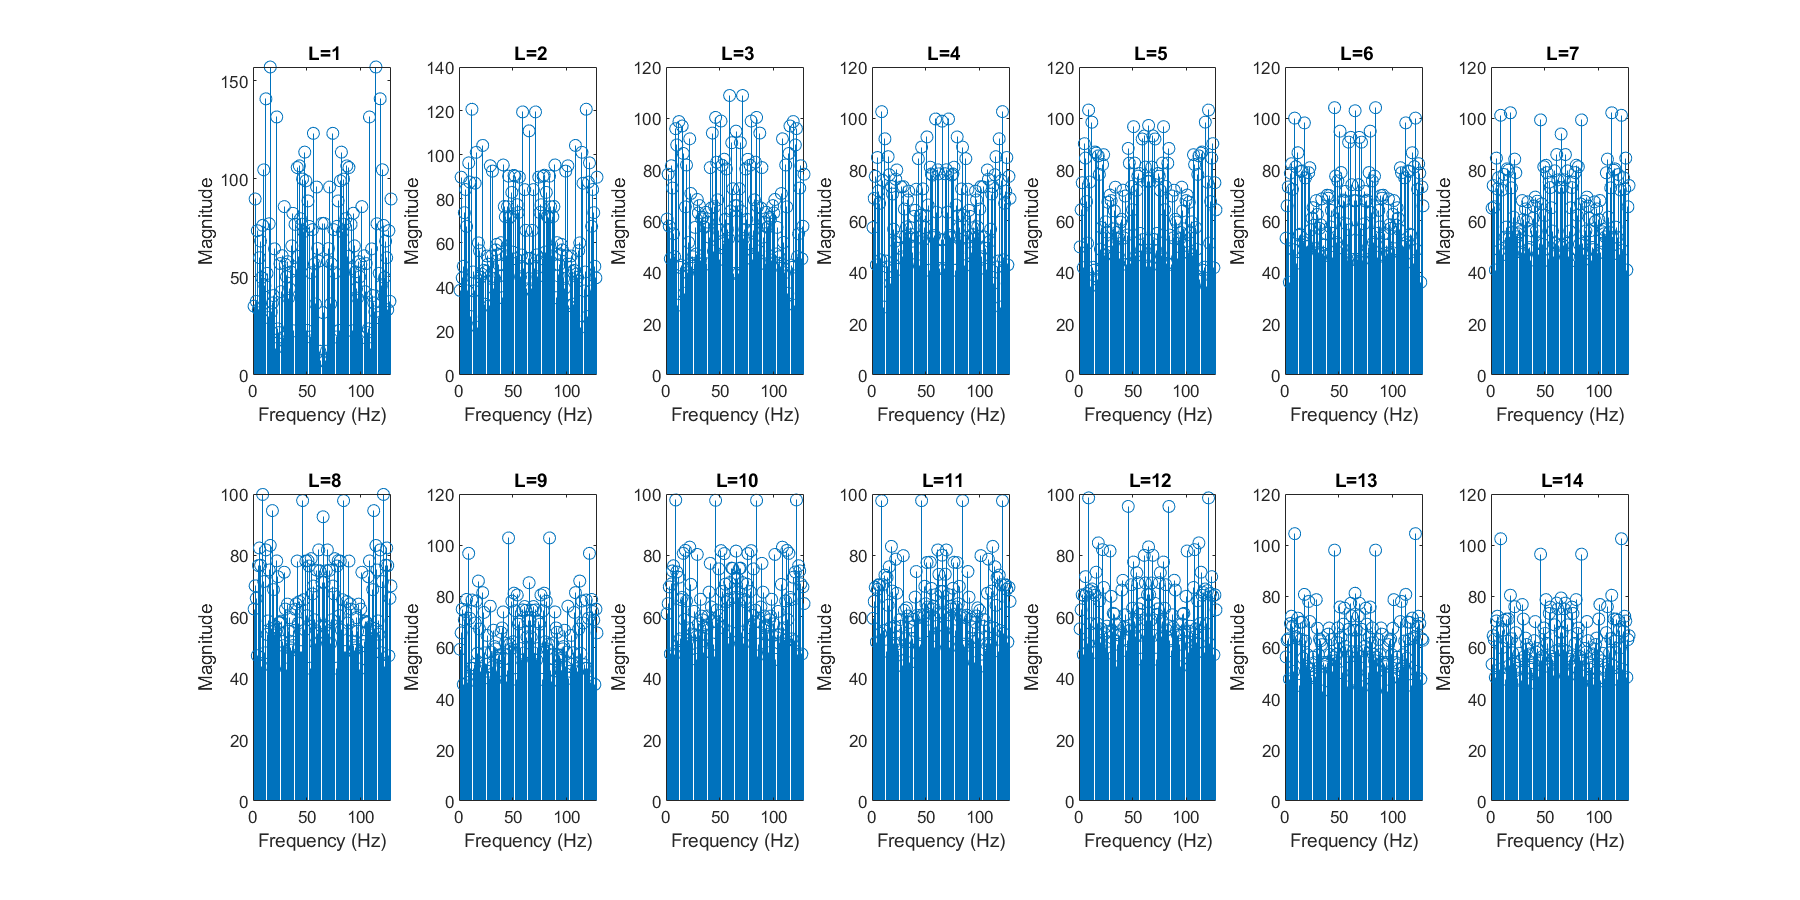

%plotting for several values of L
num_plots = 14;
rows = 2; 
cols = 7; %


figure('Position', [100, 100, 1200, 600]);

% Loop through each value of L
for L = 1:num_plots
    x = 1;
    y = 128;
    dft_mean_new = 0;

    % Compute the DFT magnitude and mean
    for n = 1:L
        subset = signal_data(x:y);
        dft_magnitude = abs(fft(subset, 128));
        dft_mean_new = dft_mean_new + dft_magnitude;

        x = y + 1;
        y = y + 128;
    end

    dft_mean_new = dft_mean_new / L;

    % Plot the average DFTs for different L values
    subplot(rows, cols, L);
    stem(dft_mean_new);
    title([' L=', num2str(L)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end

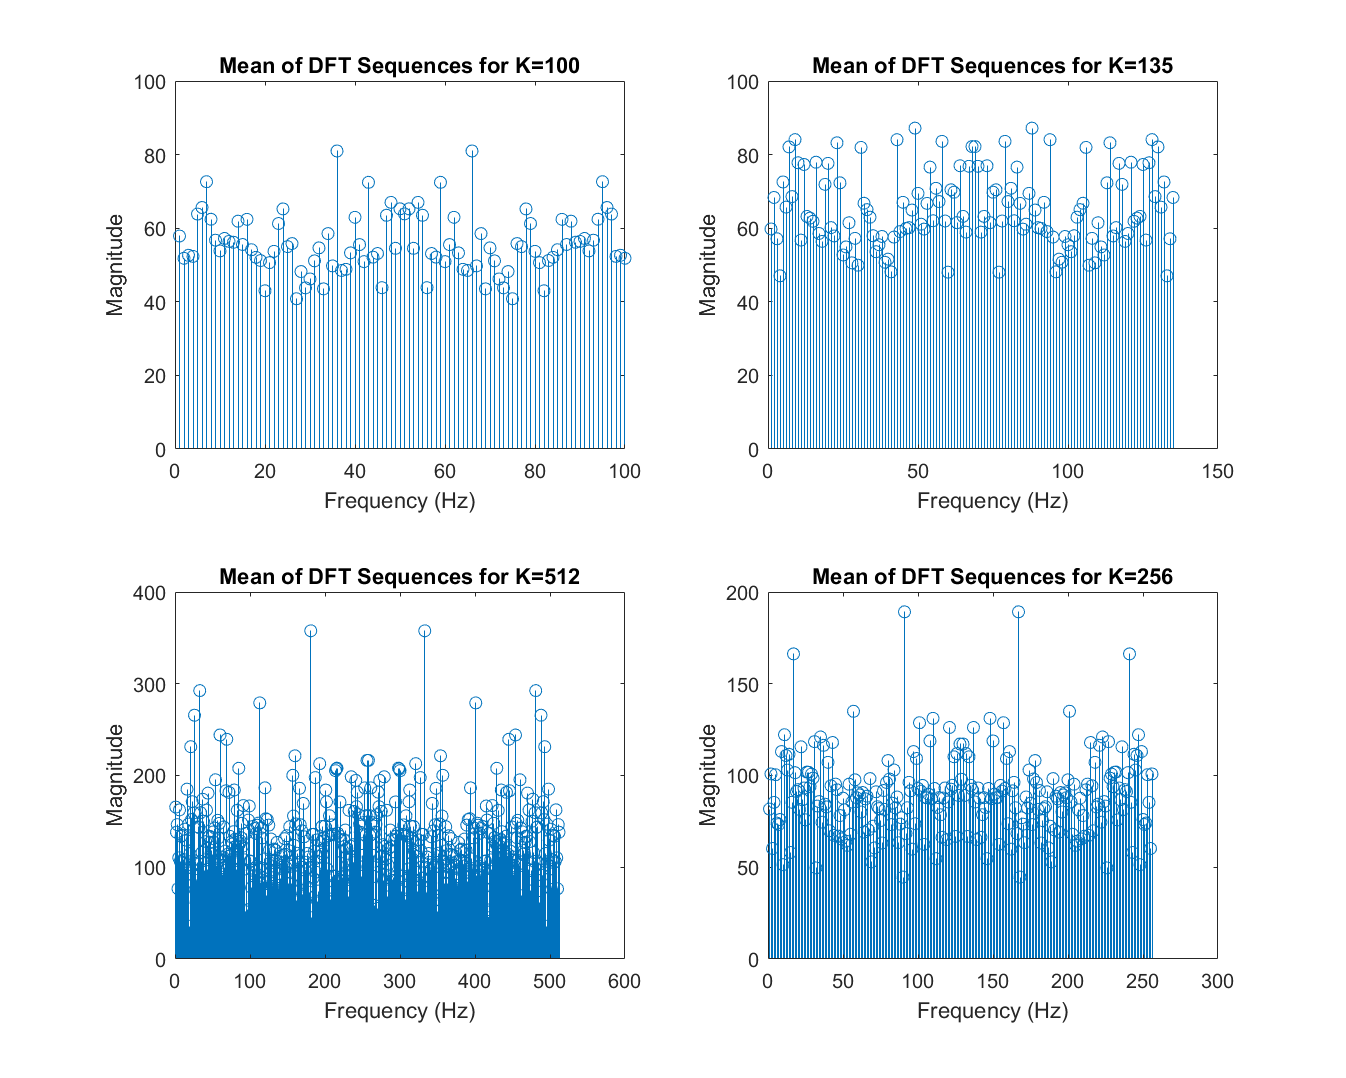


%plotting for different values of K
K = [100, 135, 512, 256];


figure('Position', [100, 100, 1000, 800]); 

% Loop through each value of K
for i = 1:length(K)
    x = 1;
    y = K(i);
    dft_mean = 0;
    subset_count = floor(length(signal_data) / K(i));

    % Compute the DFT magnitude and mean
    for j = 1:subset_count
        subset = signal_data(x:y);
        dft_magnitude = abs(fft(subset, K(i)));
        dft_mean = dft_mean + dft_magnitude;

        x = y + 1;
        y = y + K(i);
    end

    dft_mean = dft_mean / subset_count;

    % Plot the average DFTs for different K values
    subplot(2, 2, i); % 2 rows and 2 columns
    stem(dft_mean);
    title(['Mean of DFT Sequences for K=', num2str(K(i))]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end

## Interpolation

load handel;  % Load the music clip from MATLAB
N = 20000;    % Number of samples to consider
z = y(1:N);   % Extract the first 20,000 samples

x2 = z(1:2:N);  % Take every second sample
x3 = z(1:3:N);  % Take every third sample
x4 = z(1:4:N);  % Take every fourth sample


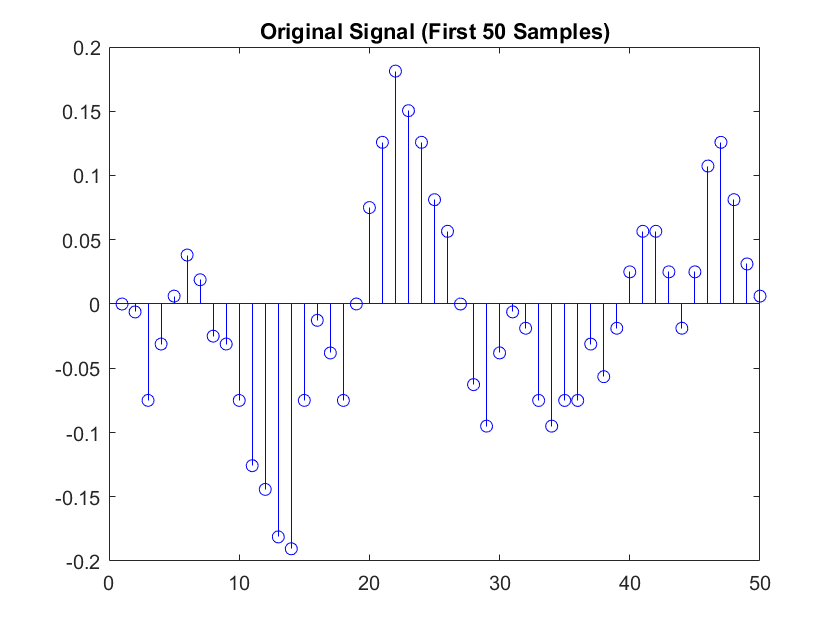

figure;
subplot(1, 1, 1);
stem(z(1:50), 'b', 'Marker', 'o');
title('Original Signal (First 50 Samples)');

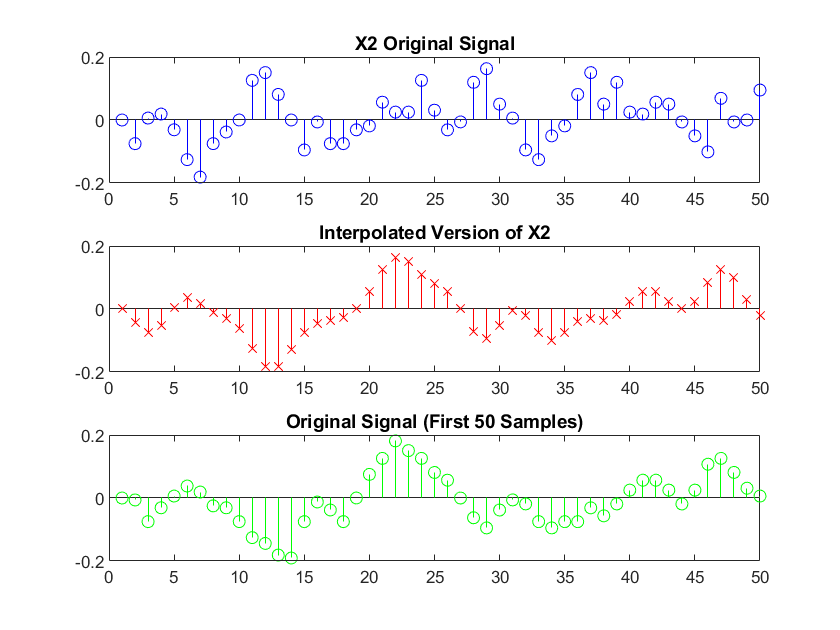

K1 = 1;
X2 = fft(x2);
N4 = length(X2);
if mod(N4, 2) == 0
 N = N4/2;
 X2_zero_padded = [X2(1:N); X2(N+1)/2; zeros((K1*N4)-1, 1); X2(N+1)/2;
X2((N+2):N4)];
else
 N = (N4+1)/2;
 X2_zero_padded = [X2(1:N); zeros(K1*N4, 1); X2((N+1):N4)];
end
interpolated_x2 = (K1+1)*ifft(X2_zero_padded);
new_x2 = interpolated_x2(1:((K1+1)*(N4-1))+2);
difference_x2 = norm(new_x2 - z);
% Plot the first 50 samples of both X2 and interpolated version of X2
% using stem plots
figure;
subplot(3,1, 1);
stem(x2(1:50), 'b', 'Marker', 'o');
title('X2 Original Signal');
subplot(3, 1, 2)
stem(new_x2(1:50), 'r', 'Marker', 'x');
title('Interpolated Version of X2');
subplot(3, 1, 3);
stem(z(1:50), 'g', 'Marker', 'o');
title('Original Signal (First 50 Samples)');

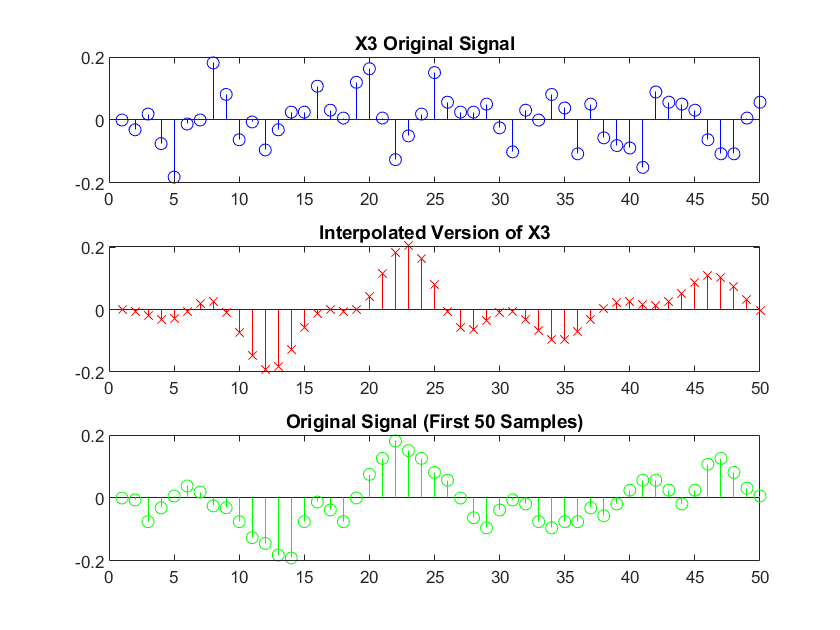

clf;
K2 = 2;
X3 = fft(x3);
N4 = length(X3);
if mod(N4, 2) == 0
 N = N4/2;
 X3_zero_padded = [X3(1:N); X3(N+1)/2; zeros((K2*N4)-1, 1); X3(N+1)/2;
X3((N+2):N4)];
else
 N = (N4+1)/2;
 X3_zero_padded= [X3(1:N); zeros(K2*N4, 1); X3((N+1):N4)];
end
interpolated_x3 = (K2+1)*ifft(X3_zero_padded);
new_x3 = interpolated_x3(1:((K2+1)*(N4-1))+2);
difference_x3 = norm(new_x3 - z);
% Plot the first 50 samples of both original and interpolated versions
% using stem plots
subplot(3, 1, 1);
stem(x3(1:50), 'b', 'Marker', 'o');
title('X3 Original Signal');
subplot(3, 1, 2)
stem(new_x3(1:50), 'r', 'Marker', 'x');
title('Interpolated Version of X3');
subplot(3, 1, 3);
stem(z(1:50), 'g', 'Marker', 'o');
title('Original Signal (First 50 Samples)');

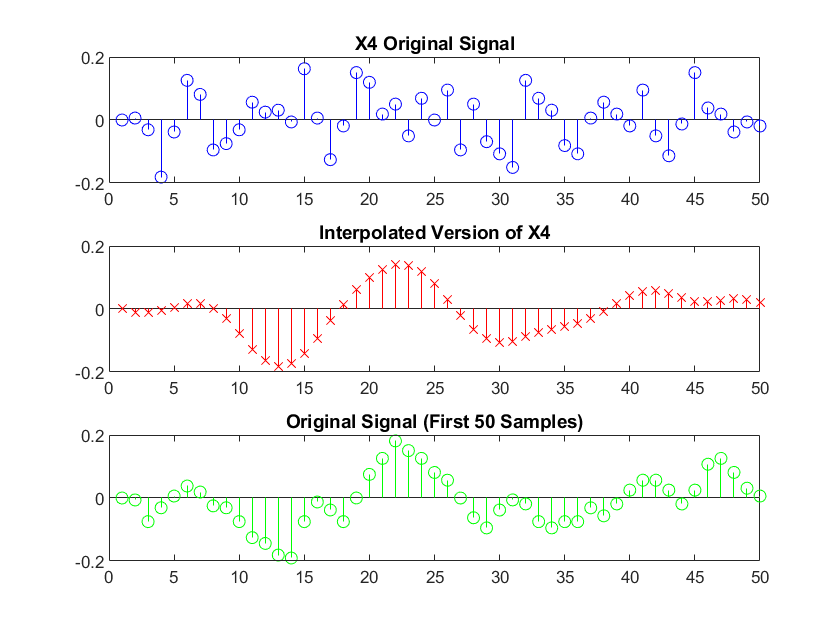

clf;
K3 = 3;
X4 = fft(x4);
N4 = length(X4);
if mod(N4, 2) == 0
 N = N4/2;
 X4_zero_padded = [X4(1:N); X4(N+1)/2; zeros((K3*N4)-1, 1); X4(N+1)/2;
X4((N+2):N4)];
else
 N = (N4+1)/2;
 X4_zero_padded = [X4(1:N); zeros(K3*N4, 1); X4((N+1):N4)];
end
interpolated_x4 = (K3+1)*ifft(X4_zero_padded);
new_x4 = interpolated_x4(1:((K3+1)*(N4-1))+4);
difference_x4 = norm(new_x4 - z);
% Plot the first 50 samples of both original and interpolated versions
% using stem plots
subplot(3, 1, 1);
stem(x4(1:50), 'b', 'Marker', 'o');
title('X4 Original Signal');
subplot(3, 1, 2)
stem(new_x4(1:50), 'r', 'Marker', 'x');
title('Interpolated Version of X4');
subplot(3, 1, 3);
stem(z(1:50), 'g', 'Marker', 'o');
title('Original Signal (First 50 Samples)');

fprintf('The difference between X2 and the original signal x in 2-norm:%f\n ', difference_x2);

The difference between X2 and the original signal x in 2-norm:6.144750
 

fprintf('The difference between X3 and the original signal x in 2-norm:%f\n ', difference_x3);

The difference between X3 and the original signal x in 2-norm:8.365213
 

fprintf('The difference between X4 and the original signal x in 2-norm:%f\n ', difference_x4);

The difference between X4 and the original signal x in 2-norm:23.499839
 